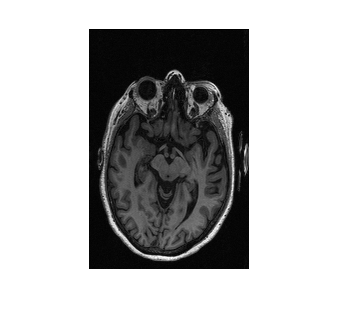

%Load the image
ImSegment = load("segmentData.mat");
ImSegment = ImSegment.data;
figure();
imshow(ImSegment, [])

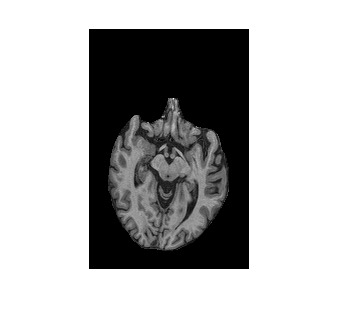

Im = load("correctedData.mat");
Im = Im.correctedData;
imshow(Im, []);

ImVals = Im(Im > 0);

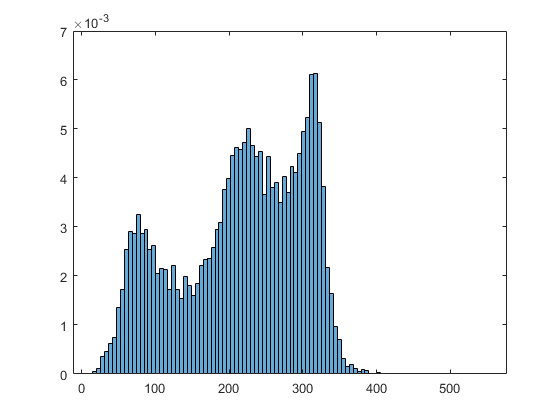

%Plot the histogram
figure();
histogram(ImVals, 100, "Normalization", "pdf");
hold on;

ImMin = min(ImVals);
ImMax = max(ImVals);
ImR = range(ImVals);

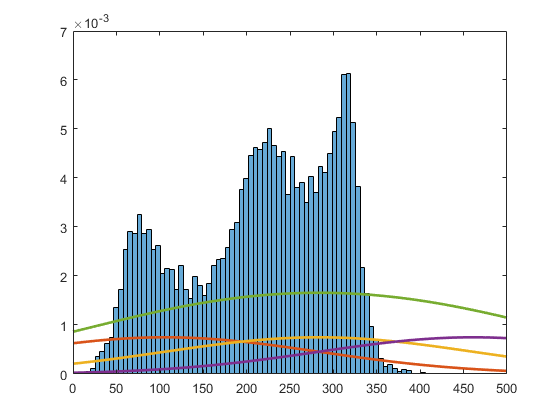

%Define the priors
pie = [1 1 1] / 3;
%Divide the range into 3 equal intervals
I1 = [ImMin ImMin + ImR / 3];
I2 = [ImMin + ImR / 3 ImMin + 2 * ImR / 3];
I3 = [ImMin + 2 * ImR / 3 ImMin + ImR];
%Define the initial means as the centers of the intervals
mu = mean([I1; I2; I3], 2)';
%Define the stamdard deviations as the width of the intervals
sigma = ones([1 3]) * (ImR / 3);
%Plot the histogram together with the 3 distributions
x = (0:1:500);
GaussComb = 0;
for i = 1:3
    plot(x, pie(i) * normpdf(x, mu(i), sigma(i)), "LineWidth", 2);
    GaussComb = GaussComb + pie(i) * normpdf(x, mu(i), sigma(i));
end
plot(x, GaussComb, "LineWidth", 2)
xlim([0 500])
hold off;

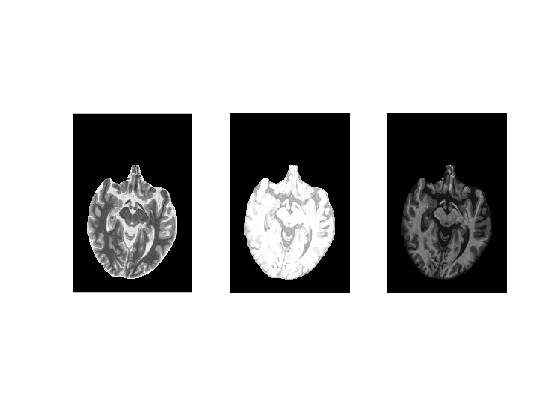

%Obtain weights 
weights = zeros([length(ImVals) 3]);

%Define the normalizing constant
normConst = 0;
for i = 1:3
    normConst = normConst + normpdf(ImVals, mu(i), sigma(i)) * pie(i);
end
%Obtain the weights (posteriors)
for i = 1:3
    weights(:, i) = (pie(i) * normpdf(ImVals, mu(i), sigma(i))) ./ normConst;
end

%Visualize the weights (posteriors)
ImPost = Im;
figure();
for i = 1:3
    subplot(1, 3, i);
    ImPost((ImPost > 0)) = weights(:, i);
    imshow(ImPost, [])
end

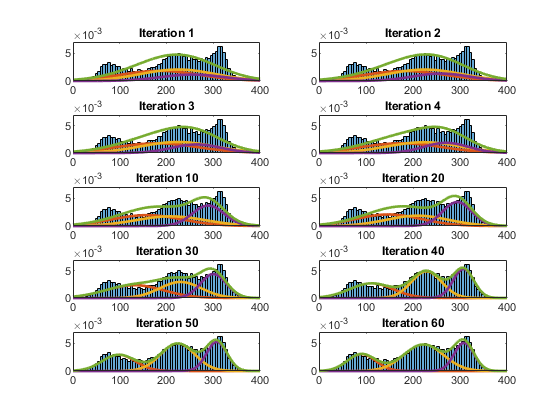

%Perform 100 iterations of the EM algorithm and visualize some of the
%iterations
plotInd = 1;
logLikelihood = zeros([1 100]);
logLikelihood1 = zeros([1 100]);
figure();
for k = 1:100
    mu = sum(weights .* ImVals, 1) ./ sum(weights, 1);
    sigma = sqrt(sum(weights .* (ImVals - mu).^2, 1) ./ sum(weights, 1));
    pie = sum(weights, 1) / length(ImVals);
    normConst = 0;
    for i = 1:3
        normConst = normConst + pie(i) * normpdf(ImVals, mu(i), sigma(i));
    end
    for i = 1:3
        weights(:, i) = (pie(i) * normpdf(ImVals, mu(i), sigma(i))) ./ normConst;
    end
%     logLikelihood(k) = sum(weights .* log((normpdf(ImVals, mu, sigma) .* pi) ./ weights), "all");
    logLikelihood(k) = sum(log(sum(normpdf(ImVals, mu, sigma) .* pie, 2)));
    if ((mod(k, 10) == 0 || k < 5) && k < 70)
        subplot(5, 2, plotInd);
        histogram(ImVals, 100, "Normalization", "pdf");
        hold on;
        x = (0:1:500);
        GaussComb = 0;
        for i = 1:3
            plot(x, pie(i) * normpdf(x, mu(i), sigma(i)), "LineWidth", 2);
            GaussComb = GaussComb + pie(i) * normpdf(x, mu(i), sigma(i));
        end
        %Plot the combined density function
        plot(x, GaussComb, "LineWidth", 2)
        xlim([0 400]);
        ylim([0 0.007])
        hold off;
        title("Iteration " + k)
        plotInd = plotInd + 1;
    end
end

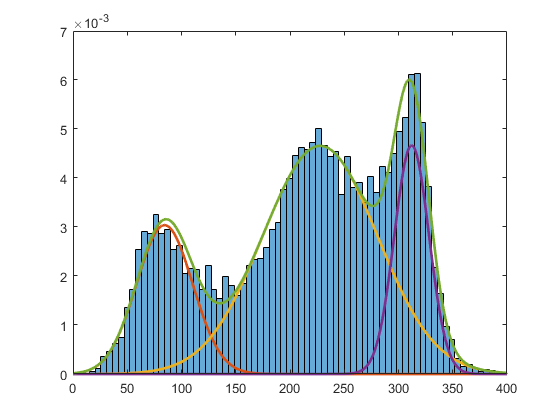

%Visualize the end results
%Plot the histogram again along with the 3 density functions
figure();
histogram(ImVals, 100, "Normalization", "pdf");
hold on;
x = (0:1:500);
GaussComb = 0;
for i = 1:3
    plot(x, pie(i) * normpdf(x, mu(i), sigma(i)), "LineWidth", 2);
    GaussComb = GaussComb + pie(i) * normpdf(x, mu(i), sigma(i));
end
%Plot the combined density function
plot(x, GaussComb, "LineWidth", 2)
xlim([0 400])
hold off;

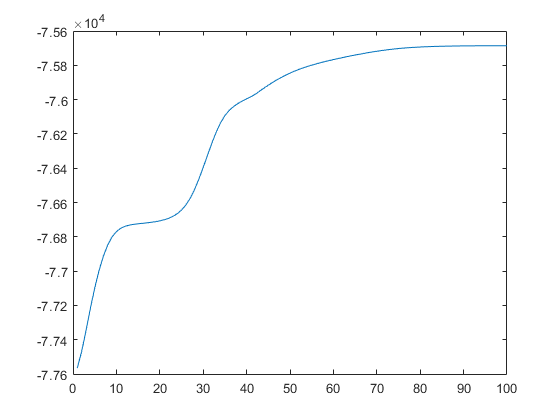

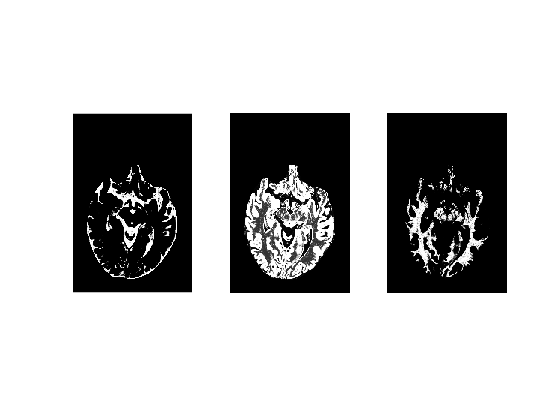

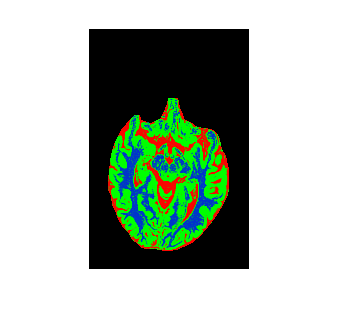

%Visualize the log-likelihood function
figure();
plot(logLikelihood);
%Visualize the posteriors
figure();
for i = 1:3
    subplot(1, 3, i);
    ImPost((ImPost > 0)) = weights(:, i);
    imshow(ImPost, [])
end

rgb = zeros([size(Im) 3]);
for i = 1:3
    ImPost(Im > 0) = weights(:, i);
    rgb(:, :, i) = ImPost;
end
figure();
imshow(rgb);

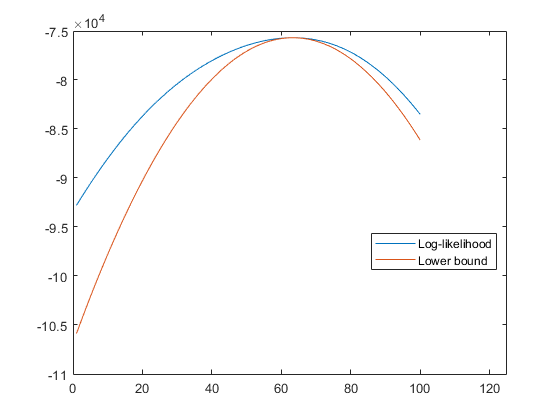

%Iterate the algorithm by varying only the mean of the 2nd distribution
%between mu1 and mu3
lowerBound = zeros([1 100]);
mu2Prog = linspace(mu(1), mu(3), 100);
muCpy = mu;
for k = 1:100
    muCpy(2) = mu2Prog(k);
    logLikelihood(k) = sum(log(sum(normpdf(ImVals, muCpy, sigma) .* pie, 2)));
    lowerBound(k) = sum(weights .* log((normpdf(ImVals, muCpy, sigma) .* pie) ./ weights), "all");
    lowerBound(k) = -0.5 * sum(1 ./ sigma.^2 .* sum(weights .* (ImVals - muCpy).^2, 1) ...
    + sum(weights, 1) .* log(sigma.^2)) + sum(sum(weights, 1) .* log(pie)) ...
    - sum(weights .* log(weights), "all") - ...
    size(weights, 1) / 2 * log(2*pi);
end
figure();
plot(logLikelihood);
xlim([0 125])
hold on;
plot(lowerBound);
legend("Log-likelihood", "Lower bound", "Location", "best");
hold off;